## Strategy Estimation for Las Vegas GP 2023

% Tyres available: C3, C4, C5 - The 3 softest in the Pirelli range.
% Race Duration: 50 laps (305.88km total distance)

% Assumption of tyre pace delta per lap: 0.5s between C5 and C4, and 0.5s
% between C4 and C3. With C5 being the fastest.

% Assumption of degradation per lap: Fuel corrected laptime increase
% linearly as tyre wears (linear tyre deg model assumed due to lack 
% of detailed information on compounds)

% Fuel correction assumption for 110kg of fuel to last 50 laps and 0.035s
% laptime gain per 1kg of fuel burn.

% Initial flying lap pace assumed due to lack of race historical data. 

Calculating Fuel Correction Factor

fuelQuantity = 110;  %kg
totalLapNumber = 50; %laps
lapNumber = 1:50;
timePerKg = 0.035;   %seconds

fuelConsumption = fuelQuantity/totalLapNumber;   %kg/lap

fuelCorrectionFactor = fuelConsumption .* timePerKg; %seconds/lap

fuelLapCorrections = fuelCorrectionFactor .* (lapNumber-1);

Defining Tyre Wear Factors

c5Wear =0.155; %s/lap
c4Wear =0.115; %s/lap
c3Wear =0.1; %s/lap

tyreAge = 1:50; %laps

Calculating Tyre Degradation Laptime Impact

c5InitialLaptime = 95;   %seconds
c4InitialLaptime = 95.5; %seconds
c3InitialLaptime = 96;   %seconds

c5TyreDegLaptime = c5InitialLaptime + c5Wear .* (tyreAge-1);
c4TyreDegLaptime = c4InitialLaptime + c4Wear .* (tyreAge-1);
c3TyreDegLaptime = c3InitialLaptime + c3Wear .* (tyreAge-1);

Calculating Tyre and Fuel Effected Laptimes for Full Distance Tyre Model

c5Laptime = c5InitialLaptime + (c5Wear .* (tyreAge-1)) - fuelLapCorrections(lapNumber);
c4Laptime = c4InitialLaptime + (c4Wear .* (tyreAge-1)) - fuelLapCorrections(lapNumber);
c3Laptime = c3InitialLaptime + (c3Wear .* (tyreAge-1)) - fuelLapCorrections(lapNumber);

To determine fuel corrected laptimes for individual stints, the following formula is appropriate:

% Fuel_Corrected_Stint_Formula = TyreDegLaptime(tyreAge(1:end_of_stint)) - fuelLapCorrections(lapNumber(stint_start_lap:stint_end_lap))

Defining Average Pit Time Loss

pitTime = 20;  %seconds

Plot Laptimes for Tyre Compounds Over Full Distance. 

This will be our estimated tyre model, from which we can devise strategy configurations and plot their corresponding race times.

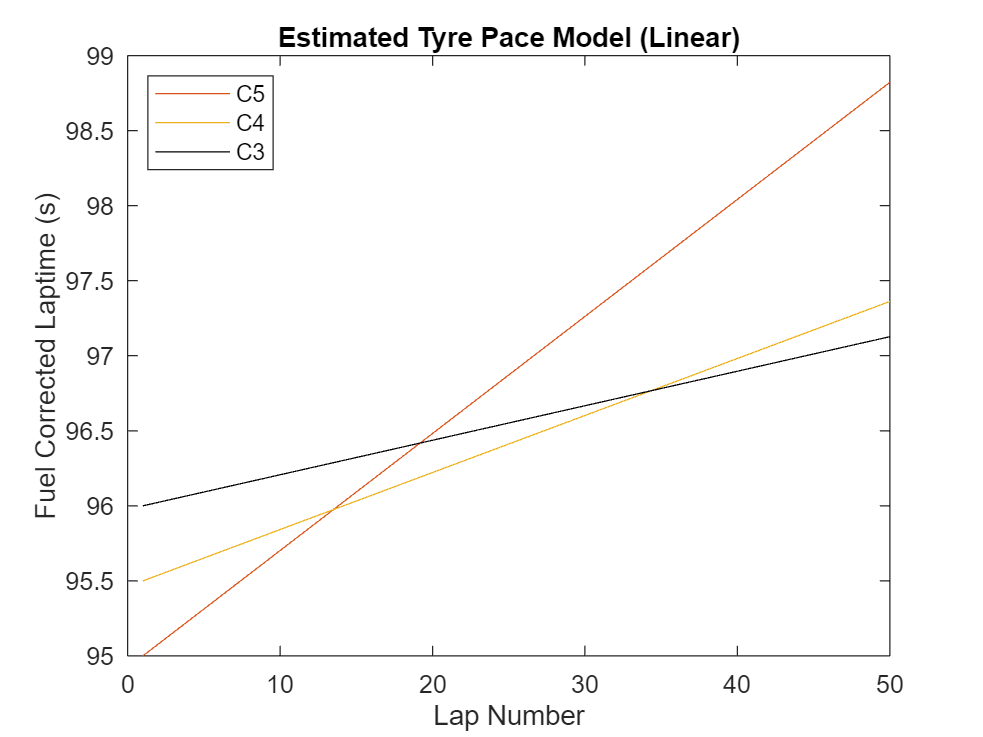

plot(lapNumber,c5Laptime,"Color","#D95319")
hold on
plot(lapNumber,c4Laptime,"Color","#EDB120")
plot(lapNumber,c3Laptime,"Color","#000000")
xlabel("Lap Number")
ylabel("Fuel Corrected Laptime (s)")
title("Estimated Tyre Pace Model (Linear)")
legend(["C5" "C4" "C3"],"Location","northwest")
hold off

Consider a single stop strategy. C5 to C4 (Soft to Medium).

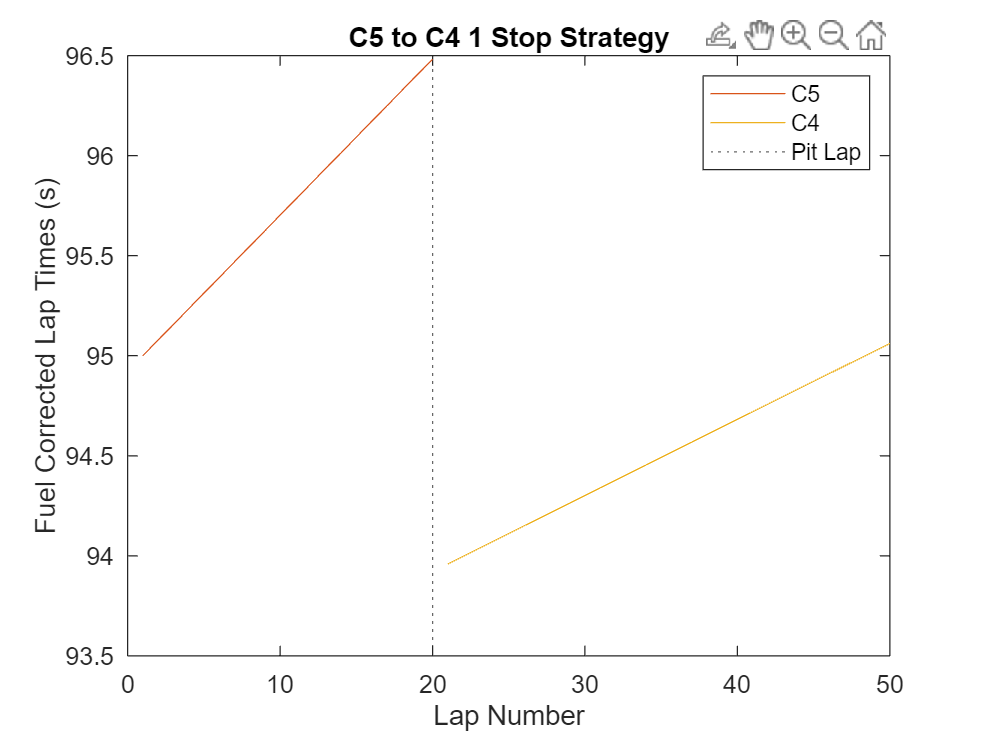

% Add slider to observe variable pitlap effects
pitLap = 20;

% Calculating fuel corrected stints
c5Fuel_Corrected_Stint = c5Laptime(tyreAge(1:pitLap));
c4Fuel_Corrected_Stint = c4TyreDegLaptime(tyreAge(1:(50-pitLap))) - fuelLapCorrections(lapNumber(pitLap+1:50));

% Plotting lap times
plot(lapNumber(1:pitLap), c5Fuel_Corrected_Stint,"Color","#D95319")
hold on
plot(lapNumber(pitLap+1:50), c4Fuel_Corrected_Stint,"Color","#EDB120")
xline(pitLap,":")
xlabel("Lap Number")
ylabel("Fuel Corrected Lap Times (s)")
title("C5 to C4 1 Stop Strategy")
legend(["C5" "C4" "Pit Lap"],"Location","northeast")
hold off


% Sum fuel corrected stint times with the pit stop time to determine
% overall race time.
totalRaceTimeC5C4_sec = seconds(sum(c5Fuel_Corrected_Stint) + sum(c4Fuel_Corrected_Stint) + pitTime)  %seconds

totalRaceTimeC5C4_sec = duration
   4770.1 sec


totalRaceTimeC5C4_min = minutes(minutes(totalRaceTimeC5C4_sec))

totalRaceTimeC5C4_min = duration
   79.502 min


Consider a single stop strategy. C4 to C3 (Medium to Hard).

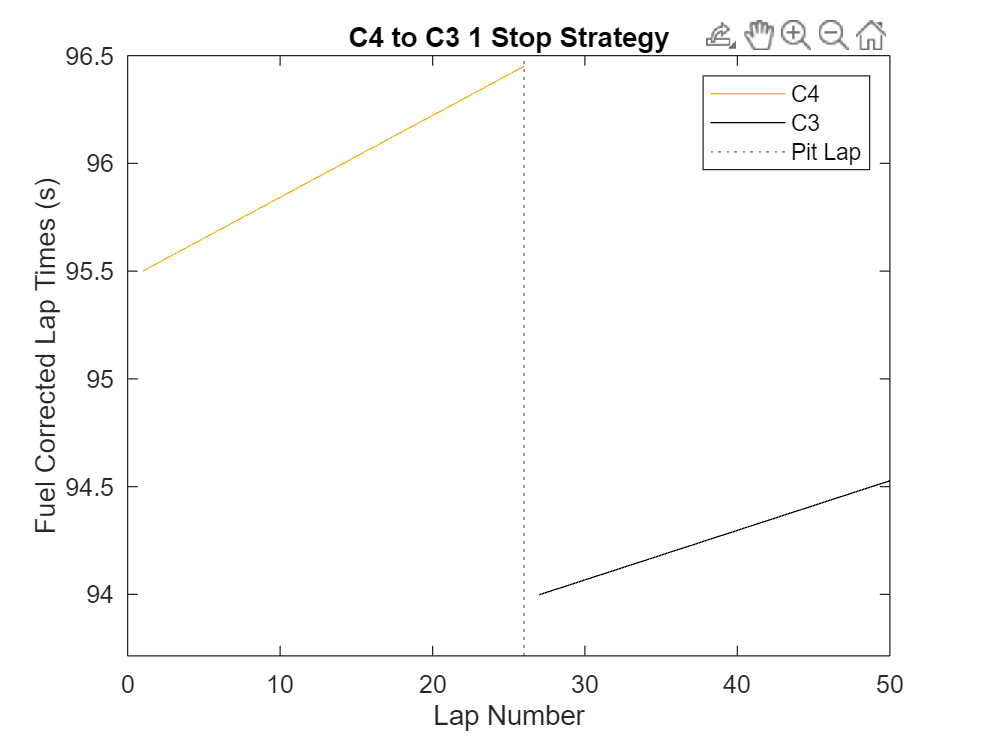

% Add slider to observe variable pitlap effects
pitLap = 26;

% Calculating fuel corrected stints
c4Fuel_Corrected_Stint = c4Laptime(tyreAge(1:pitLap));
c3Fuel_Corrected_Stint = c3TyreDegLaptime(tyreAge(1:(50-pitLap))) - fuelLapCorrections(lapNumber(pitLap+1:50));

% Plotting lap times
plot(lapNumber(1:pitLap), c4Fuel_Corrected_Stint,"Color","#EDB120")
hold on
plot(lapNumber(pitLap+1:50), c3Fuel_Corrected_Stint,"Color","#000000")
xline(pitLap,":")
xlabel("Lap Number")
ylabel("Fuel Corrected Lap Times (s)")
title("C4 to C3 1 Stop Strategy")
legend(["C4" "C3" "Pit Lap"],"Location","northeast")
hold off


% Sum fuel corrected stint times with the pit stop time to determine
% overall race time.
totalRaceTimeC4C3_sec = seconds(sum(c4Fuel_Corrected_Stint) + sum(c3Fuel_Corrected_Stint) + pitTime)  %seconds

totalRaceTimeC4C3_sec = duration
   4777.6 sec


totalRaceTimeC4C3_min = minutes(minutes(totalRaceTimeC4C3_sec))  %minutes

totalRaceTimeC4C3_min = duration
   79.627 min


Consider a 2 stop strategy. C5, C5, C4 (Soft, Soft, Medium).

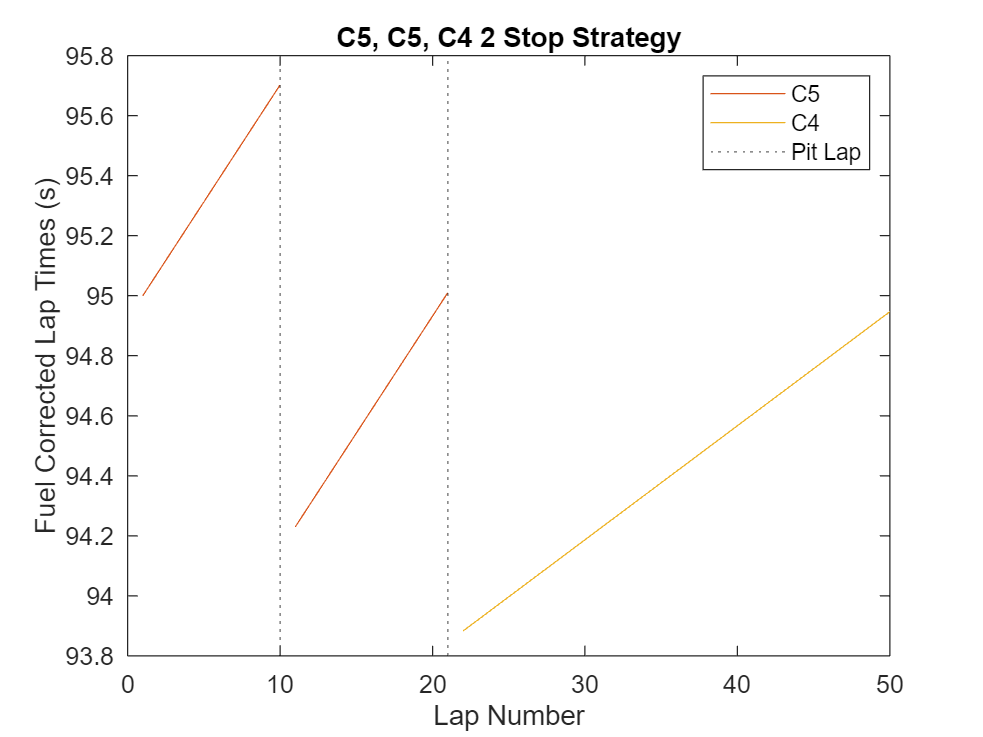

% Add sliders to observe variable pitlap effects
pitLap1 = 10;
pitLap2 = 21;

% Calculating fuel corrected stints
c5Fuel_Corrected_Stint1 = c5Laptime(tyreAge(1:pitLap1));
c5Fuel_Corrected_Stint2 = c5TyreDegLaptime(tyreAge(1:pitLap2-pitLap1)) - fuelLapCorrections(lapNumber(pitLap1+1:pitLap2));
c4Fuel_Corrected_Stint = c4TyreDegLaptime(tyreAge(1:(50-pitLap2))) - fuelLapCorrections(lapNumber(pitLap2+1:50));

% Plotting lap times
plot(lapNumber(1:pitLap1), c5Fuel_Corrected_Stint1,"Color","#D95319")
hold on
plot(lapNumber(pitLap1+1:pitLap2), c5Fuel_Corrected_Stint2,"Color","#D95319")
plot(lapNumber(pitLap2+1:50), c4Fuel_Corrected_Stint,"Color","#EDB120")
xline(pitLap1,":")
xline(pitLap2,":")
xlabel("Lap Number")
ylabel("Fuel Corrected Lap Times (s)")
title("C5, C5, C4 2 Stop Strategy")
legend(["C5" "" "C4" "Pit Lap" ""],"Location","northeast")
hold off


% Sum fuel corrected stint times with the pit stop time to determine
% overall race time.
totalRaceTimeC5C5C4_sec = seconds(sum(c5TyreDegLaptime(tyreAge(1:pitLap1))) + sum(c5TyreDegLaptime(tyreAge(pitLap1:pitLap2))) + sum(c4TyreDegLaptime(tyreAge(1:(50-pitLap2)))) + (2.*pitTime))  %seconds

totalRaceTimeC5C5C4_sec = duration
   4980.1 sec


totalRaceTimeC5C5C4_min = minutes(minutes(totalRaceTimeC5C5C4_sec))  %minutes

totalRaceTimeC5C5C4_min = duration
   83.002 min
